In =      1     0     0
     0     1     0
     0     0     1


$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & 0 & -\frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & -\frac{R}{L} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ \frac{1}{L} \end{array}\right)$$

C =      1     0     0


$$X = \left(\begin{array}{ccc} s & -1 & 0\\ -\frac{{X_{3}}^{2}\,c}{{X_{1}}^{2}\,m} & s & \frac{2\,X_{3}\,c}{X_{1}\,m}\\ 0 & 0 & s+\frac{R}{L} \end{array}\right)$$

$$Y = \begin{array}{l} \left(\begin{array}{ccc} -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c}{\sigma_{1}\,\left(R+L\,s\right)}\\ -\frac{{X_{3}}^{2}\,c}{\sigma_{1}} & -\frac{{X_{1}}^{2}\,m\,s}{\sigma_{1}} & \frac{2\,L\,X_{1}\,X_{3}\,c\,s}{\sigma_{1}\,\left(R+L\,s\right)}\\ 0 & 0 & \frac{L}{R+L\,s} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={X_{3}}^{2}\,c-{X_{1}}^{2}\,m\,s^{2} \end{array}$$

$$q1 = \frac{962361}{980}$$

$$q2 = -\frac{981}{350}$$

$$q4 = 100$$

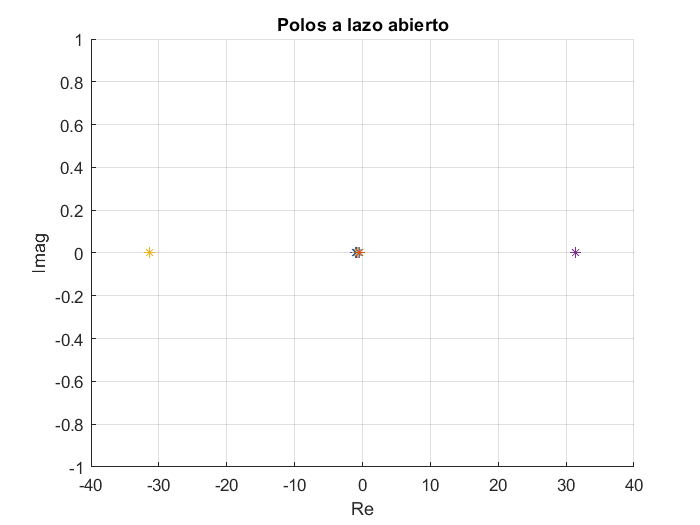

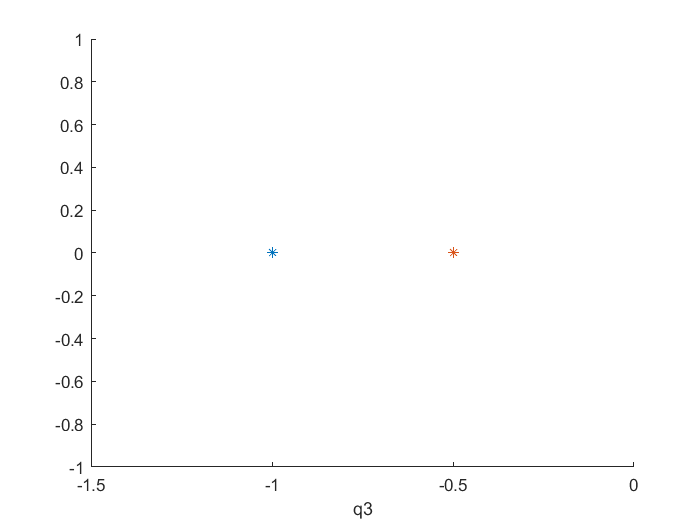

$$A1 = \left(\begin{array}{ccc} 0 & 1 & 0\\ 982.0010204315185546875 & 0 & -\frac{981}{350}\\ 0 & 0 & -1 \end{array}\right)$$

$$A2 = \left(\begin{array}{ccc} 0 & 1 & 0\\ \frac{962361}{980} & 0 & -2.802857142873108386993408203125\\ 0 & 0 & -\frac{1}{2} \end{array}\right)$$

$$B = \left(\begin{array}{c} 0\\ 0\\ 100.0 \end{array}\right)$$


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                        0.022887
     2                        0.020150
     3                        0.020150
     4                    5.396874e-03
     5                    3.464740e-03
     6                    1.175844e-03
     7                    4.253906e-04
     8                    4.253906e-04
     9                    4.253906e-04
    10                    2.664004e-04
    11                    2.664004e-04
    12                    3.885984e-05
    13                    3.885984e-05
    14                    1.070217e-05
    15                    1.070217e-05
    16                    1.763750e-06
***                 new lower bound: -8.495514e-07
    17                    5.389128e-07
***                 new lower bound: -2.430204e-07
    18               

K =    65.7492    3.9276   -0.1770


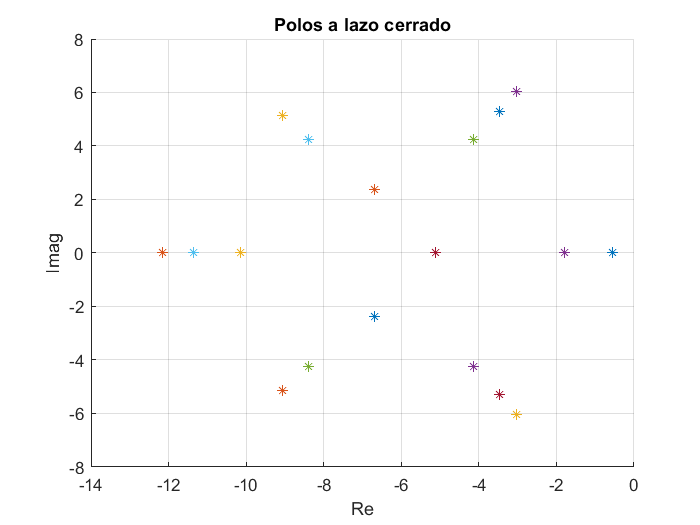

% definimos la variable compleja s
syms s c m R g L V x1 x2 x3 X1 X2 X3 % X mayuscula es para el punto de equilibrio; c = constante; m = masa ; R = resistencia; L = inductancia; V = tensión; g = gravedad
% In
In =  [1 0 0;0 1 0;0 0 1]
% A
A = [0 1 0; (c*X3^2)/(m*X1^2) 0 (-2*c*X3)/(m*X1);0 0 -R/L]
% B
B = [0;0;1/L]
% C 
C = [1 0 0]
% sIn - A 
X = s*In - A
% inversa 
Y = inv(X)



% Tomando como valores variables la masa y la resistencia y valores fijos
% la constante "c", la masa "M" y la tensión "V"

%q1 A(2,1) 
q1 =  (c*(V/R)^2)/(m*(((c*V^2)/(m*g*R^2)))^2);
%q2 A(2,3)
q2 = -1 * ((2*V/R*c)/(m*(c*V^2)/(m*g*R^2)));
%q3 A(3,3)
q3 = -R/L;
%q4 B(3,1)
q4 = 1/L;

% Sustituimos los valores por defecto 

q1 = subs(q1, [c V g m R], [0.0001, 7, 9.81 0.05 1])

q2 = subs(q2, [c V g m R], [0.0001, 7, 9.81 0.05 1])

q4 = subs(q4, L, 0.01)
% La variación en el tiempo de q1 y q2 en el tiempo sera de un 5% arriba y
% hacia abajo (definición del politopo)

%q4 pertenece a:


figure
for  Q3=-1:0.1:-0.5
    A=[0 1 0; q1 0 q2; 0 0 Q3];
    p=eig(A);
    hold on
    plot(real(p(1)),imag(p(1)),'*')
    plot(real(p(2)),imag(p(2)),'*')
    plot(real(p(3)), imag(p(3)), '*')
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo abierto')
hold off


% Dibujamos la linea
figure
hold on


plot(-1, 0, '*')
plot(-0.5, 0, '*')
axis([-1.5 0 -1 1])
xlabel('q3')
hold off

% Creamos la desigualdad lineal matricial 


% Realimentación de estado + reubicación de polos en región R(Alfa,Ro) 
% Theta = 0.

% Planta
A1=[0 1 0;vpa(q1,2) 0 q2; 0 0 -1]

A2=[0 1 0;q1 0 vpa(q2,2); 0 0 -0.5]

B=[0; 0; vpa(q4,2)]

% Todos estos valores dan estable
% a 1.4
% b 10
% 
% a 1.2
% b 10
% 
% a 0.9
% b 10
% 
% a 0.8
% b 10
% 
% a 0.7
% b 10
% 
% a 0
% b 9
% Especificaciones región reubicación de polos
Alfa=2;
Ro=7;

% Creación sistema LMI
setlmis([])

% Variables LMIs
S=lmivar(1,[3 1]); % S(3,3) simétrica, 3x3 porque A es de 3x3 
R=lmivar(2,[1 3]); % R(1,2) arbitraria, 1x3 porque B es de 1x3

% S > 0

lmiterm([-1 1 1 S],1,1);

% Restricciones asociadas al parámetro Alfa

% 𝑨𝑺 + 𝑺𝑨𝑻 + 𝑩1S + 𝑹𝑩1 + 𝟐𝜶𝑺 < 𝟎
lmiterm([2 1 1 S],A1,1,'s');
lmiterm([2 1 1 R],B,1,'s');
lmiterm([2 1 1 S],2*Alfa,1);

% 𝑨𝑺 + 𝑺𝑨𝑻 + 𝑩2R + 𝑹𝑩2 + 𝟐𝜶𝑺 < 𝟎
lmiterm([3 1 1 S],A2,1,'s');
lmiterm([3 1 1 R],B,1,'s');
lmiterm([3 1 1 S],2*Alfa,1);


% Restricciones asociadas al parámetro Ro

% (A,B1)
lmiterm([6 1 1 S],-Ro,1);
lmiterm([6 1 2 S],A1,1);
lmiterm([6 1 2 R],B,1);
lmiterm([6 2 2 S],-Ro,1);

% (A,B2)
lmiterm([7 1 1 S],-Ro,1);
lmiterm([7 1 2 S],A2,1);
lmiterm([7 1 2 R],B,1);
lmiterm([7 2 2 S],-Ro,1);


% Ejecución del solver
LMISYS=getlmis;
[tmin,xfeas]=feasp(LMISYS);

% Solución
S=dec2mat(LMISYS,xfeas,S);
R=dec2mat(LMISYS,xfeas,R);

K=R*inv(S)


% Polos a lazo cerrado del sistema  politópico

syms R
figure
for Q3=-1:0.1:-0.5
        A=[0 1 0;q1 0 q2; 0 0 Q3];
        B=[0; 0; subs(q4, L, l)];
        p=eig(A+B*K);
        hold on
        plot(real(p(1)),imag(p(1)),'*');
        plot(real(p(2)),imag(p(2)),'*');
        plot(real(p(3)), imag(p(3)), '*');
    
end
grid
xlabel('Re'), ylabel('Imag'), title('Polos a lazo cerrado')
hold off

